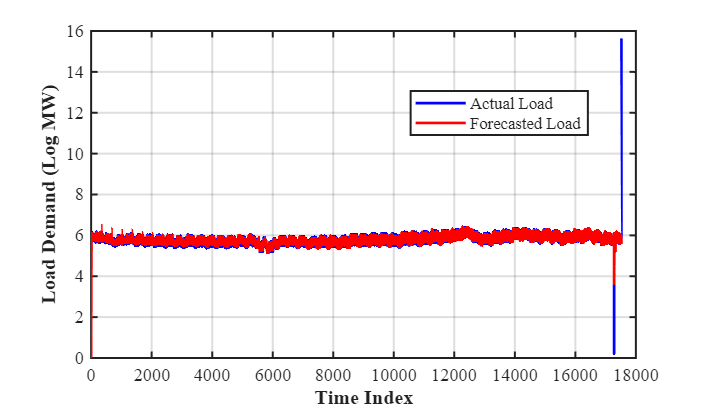

clc; clear; close all;

%% =====================================================
% IC LOAD FORECASTING MODEL (CONFERENCE PAPER VERSION)
% Includes:
% 1. Actual vs Forecast Plot
% 2. Zoom Plot
% 3. MAPE vs Horizon Plot
% 4. PNG Export (600 DPI)
%% =====================================================

%% =========================
% LOAD DATA
%% =========================
data = readtable('Complete datasheet (1).csv');

y = double(data.Log_MW);
y = fillmissing(y,'linear');

T = length(y);

%% =========================
% PARAMETERS
%% =========================
m = 48;            % 48 half-hours per day
alpha = 0.20;
delta = 0.10;

%% =========================
% DAY TYPE CREATION
% 1 = Monday
% 2 = Tuesday
% 3 = Wed/Thu/Fri
% 4 = Saturday
% 5 = Sunday
%% =========================
day_idx = mod(floor((0:T-1)/m),7) + 1;

day_type = zeros(T,1);

for i = 1:T
    
    d = day_idx(i);
    
    if d == 1
        day_type(i) = 1;
    elseif d == 2
        day_type(i) = 2;
    elseif d <= 5
        day_type(i) = 3;
    elseif d == 6
        day_type(i) = 4;
    else
        day_type(i) = 5;
    end
end

%% =========================
% INITIALIZATION
%% =========================
l = zeros(T,1);
d_season = zeros(m,5);
y_pred = zeros(T,1);

l(1) = y(1);

%% =========================
% IC MODEL TRAINING
%% =========================
for t = m+1:T
    
    type = day_type(t);
    idx  = mod(t-1,m) + 1;
    
    y_pred(t) = l(t-1) + d_season(idx,type);
    
    e = y(t) - y_pred(t);
    
    l(t) = l(t-1) + alpha*e;
    d_season(idx,type) = d_season(idx,type) + delta*e;
end

valid = m+1:T;

%% =====================================================
% FIGURE 1 : ACTUAL vs FORECAST
%% =====================================================
figure('Color','w','Position',[100 100 720 420]);

plot(y(valid),'b','LineWidth',1.6); hold on;
plot(y_pred(valid),'r','LineWidth',1.6);

grid on;
box on;

xlabel('Time Index','FontSize',12,'FontWeight','bold');
ylabel('Load Demand (Log MW)','FontSize',12,'FontWeight','bold');

legend({'Actual Load','Forecasted Load'},...
    'Location','best','FontSize',10);

set(gca,...
    'FontName','Times New Roman',...
    'FontSize',11,...
    'LineWidth',1.2);

exportgraphics(gcf,'IC_Actual_vs_Forecast.png','Resolution',600);

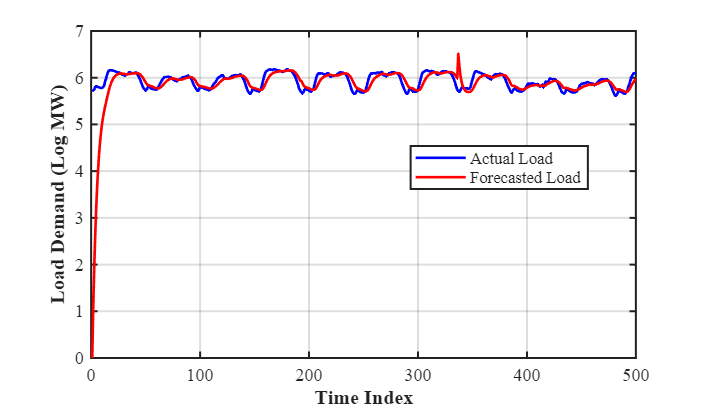


%% =====================================================
% FIGURE 2 : ZOOM VIEW
%% =====================================================
figure('Color','w','Position',[120 120 720 420]);

plot(y(valid(1:500)),'b','LineWidth',1.6); hold on;
plot(y_pred(valid(1:500)),'r','LineWidth',1.6);

grid on;
box on;

xlabel('Time Index','FontSize',12,'FontWeight','bold');
ylabel('Load Demand (Log MW)','FontSize',12,'FontWeight','bold');

legend({'Actual Load','Forecasted Load'},...
    'Location','best','FontSize',10);

set(gca,...
    'FontName','Times New Roman',...
    'FontSize',11,...
    'LineWidth',1.2);

exportgraphics(gcf,'IC_Zoom_View.png','Resolution',600);

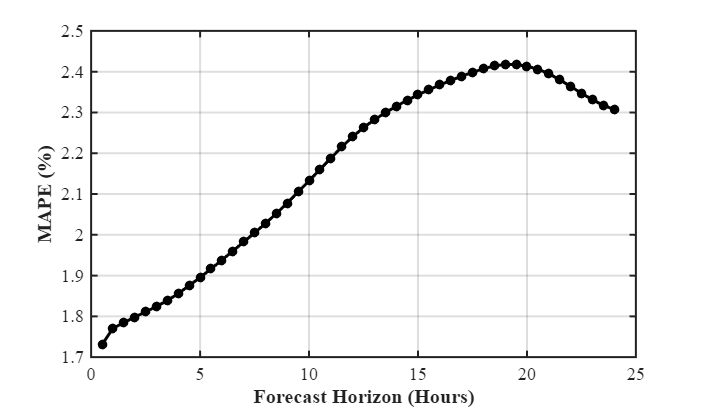


%% =========================
% MAPE vs HORIZON
%% =========================
max_h = 48;
MAPE = zeros(max_h,1);

for h = 1:max_h
    
    err = [];
    
    for t = m:(T-h)
        
        type = day_type(t+h);
        idx  = mod(t+h-1,m) + 1;
        
        y_hat = l(t) + d_season(idx,type);
        y_true = y(t+h);
        
        if y_true ~= 0
            err = [err; abs((y_true-y_hat)/y_true)];
        end
    end
    
    MAPE(h) = mean(err)*100;
end

%% =====================================================
% FIGURE 3 : MAPE vs HORIZON
%% =====================================================
figure('Color','w','Position',[140 140 720 420]);

plot((1:max_h)/2,MAPE,'k-o',...
    'LineWidth',1.8,...
    'MarkerSize',4,...
    'MarkerFaceColor','k');

grid on;
box on;

xlabel('Forecast Horizon (Hours)',...
    'FontSize',12,'FontWeight','bold');

ylabel('MAPE (%)',...
    'FontSize',12,'FontWeight','bold');

set(gca,...
    'FontName','Times New Roman',...
    'FontSize',11,...
    'LineWidth',1.2);

exportgraphics(gcf,'IC_MAPE_vs_Horizon.png','Resolution',600);


%% =====================================================
% TABLE OUTPUT
%% =====================================================
horizon = (1:max_h)'/2;

MAPE_Table = table(horizon,MAPE,...
    'VariableNames',{'Horizon_Hours','MAPE_percent'});

disp(MAPE_Table);

    Horizon_Hours    MAPE_percent
    _____________    ____________

         0.5            1.7306   
           1            1.7706   
         1.5            1.7846   
           2            1.7979   
         2.5            1.8111   
           3            1.8242   
         3.5            1.8391   
           4             1.856   
         4.5            1.8753   
           5            1.8956   
         5.5            1.9164   
           6             1.938   
         6.5            1.9602   
           7            1.9824   
         7.5            2.0047   
           8            2.0279   
         8.5            2.0522   
           9            2.0779   
         9.5            2.1052   
          10            2.1324   
        10.5            2.1601   
          11            2.1879   
        11.5            2.2153   
          12            2.2405   
        12.5            2.2627   
          13 


writetable(MAPE_Table,'IC_MAPE_Table.csv');

%% =====================================================
% ERROR METRICS
%% =====================================================
rmse = sqrt(mean((y(valid)-y_pred(valid)).^2));
mae  = mean(abs(y(valid)-y_pred(valid)));

fprintf('\nRMSE = %.4f\n',rmse);


RMSE = 0.1344


fprintf('MAE  = %.4f\n',mae);

MAE  = 0.0489



disp('Saved Files:');

Saved Files:


disp('1. IC_Actual_vs_Forecast.png');

1. IC_Actual_vs_Forecast.png


disp('2. IC_Zoom_View.png');

2. IC_Zoom_View.png


disp('3. IC_MAPE_vs_Horizon.png');

3. IC_MAPE_vs_Horizon.png


disp('4. IC_MAPE_Table.csv');

4. IC_MAPE_Table.csv
